Median Estimator

A=1;
sigma = sqrt(10.^(-linspace(0,3)));
N=1000;
numSamp = 10000

numSamp = 10000


res = zeros(size(sigma));
for ind = 1:numel(sigma)
    s = sigma(ind);
    x = A + randn(N,numSamp) * s;
    m = median(x);
    e = m - A;
    res(ind) = mean(e.^2);
end

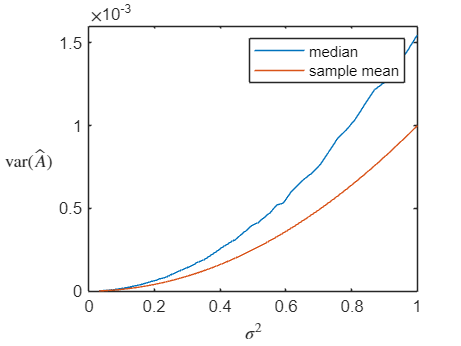

figure;
plot(sigma, res, 'DisplayName', 'median');
hold on;
plot(sigma, sigma.^2/N, 'DisplayName', 'sample mean');
ylabel('var($\hat{A}$)', 'Interpreter', 'latex');
xlabel('$\sigma^2$', 'Interpreter', 'latex');
set(get(gca,'ylabel'),'rotation',0);
legend();